# PV emulator curves

First, we are going to test the equations:


$$I=N_PI_{PH}-N_PI_S[e^{(q(V/N_S+iR_s/N_P)/kT_{cell}A)}-1]-(N_PV/N_S+iR_S)/R_{SH}$$


We want to plot the curves for different temperatures and different irradiation

for that we use the pv_math function, which is a script that  uses the samle mathematical model as what is implemented in the PV model simulink...

type pv_math_CTJ.m

function I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i)
    q = 1.6e-19;                           % Electron charge
    k = 1.38e-23;                          % Boltzmann constant
    Tcell = 273+T;                         % Cell temperature in Kelvin
    vt=(A*k*Tcell*Ns)/q;                   % Thermal voltage Equation(5)
        
    Isc_T = Isc+((Isc*(Ki/1000))*(T-25));  % Isc temperature coef Equation(6)
    Voc_T = Voc+((Voc*(Kv/1000))*(T-25));  % Voc temperature coef Equation(7)
    Is = Isc_T/(exp(Voc_T/vt)-1);          % Reverse saturation current Equation(8)
    Iph = Isc_T*(G/1367);                  % Photon current Equation(9)
    
    if V>Voc_T
        V=Voc_T;
    end
    % Single diode model output current Equation(4)
    I = Np*Iph-Np*Is*(exp(q*(V/Ns+i*Rs/Np)/(k*Tcell*A) ) -1) -(Np*V/Ns+i*Rs)/Rsh ;
    I(I < 0) = 0;
end


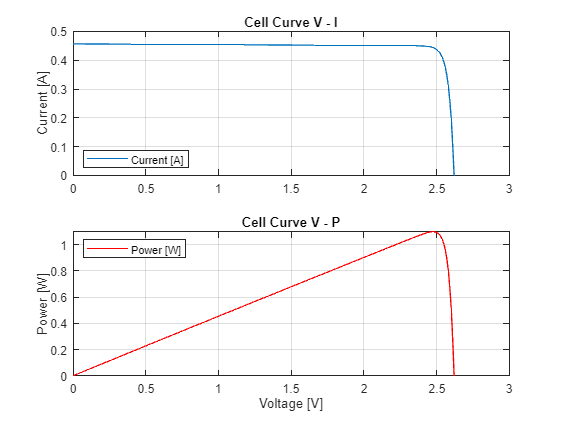

clear all
close all
G=1367;
T=25;
Isc=0.457;
Voc=2.62;
A=1.3;
%A=0.00265;
% Ki=0.36e-3;
% Kv=-6.7e-3;
Rs=1.3;
Rsh=362;
Ns=1;
Np=1;
size=26.5;          % in cm^2
%k_i=0.102;
k_i=0.0114*size;    % in [mA / cm^2 / deg C]
%k_v=-0.36099;
k_v=-6.19;          % in [mV / deg C]
i=0;
V=0:0.01:Voc+0.01;


% clear all
% close all
% G=1000;
% T=25;
% Isc=1.25;
% Voc=21.7;
% A=0.97;
% Rs=1.3;
% Rsh=362;
% Ns=36;
% Np=1;
% k_i=0.102;
% k_v=-0.36099;
% i=0;
% V=0:0.1:21.4;

%I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,k_i,k_v,V,i);
I = pv_math_CTJ(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,k_i,k_v,V,i);
figure(1)
set(gcf,'color','w');
subplot(2,1,1)
    plot(V,I)
    grid on
    legend('Current [A]')
    legend('Location','southwest')
    title('Cell Curve V - I')
    ylabel('Current [A]')
    %xlabel('Voltage [V]')
subplot(2,1,2)
    plot(V,V.*I,'r')
    grid on
    legend('Power [W]')
    legend('Location','northwest')
    title('Cell Curve V - P')
    ylabel('Power [W]')
    xlabel('Voltage [V]')

## 3U CubeSat, 1 solar panel 7S1P

Using the values of the MSP IonSat Solar panel, which has 4 blocks of 4S1P in parallel, which give in total 4S4P , The value of A is found from this article Tsai, H. L., Tu, C. S., & Su, Y. J. (2008, October). Development of generalized photovoltaic model using MATLAB/SIMULINK. In *Proceedings of the world congress on Engineering and computer science* (Vol. 2008, pp. 1-6).

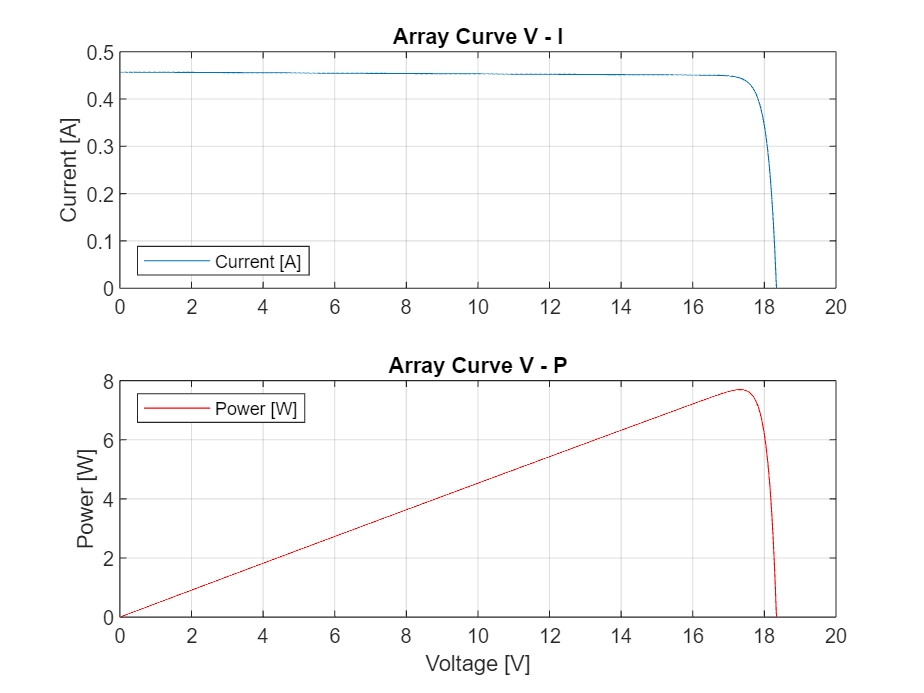

Ns=7;
Np=1;
G=1367;
T=25;
Isc=0.457; %cell
%Voc=Ns*2.69; %array
Voc=Ns*2.62; %array
A=1.3;
Rs=1.3;
Rsh=362;
% Ki=0.36e-3;
% Kv=-6.7e-3;
size=26.5;          % in cm^2
Ki=0.0114*size;    % in [mA / cm^2 / deg C]
Kv=-6.19;         % in [mV / deg C]  
i=0;
V=0:0.01:Voc+0.01;
I = pv_math_CTJ(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
figure(2)
set(gcf,'color','w');
subplot(2,1,1)
    plot(V,I)
    grid on
    legend('Current [A]')
    legend('Location','southwest')
    title('Array Curve V - I')
    ylabel('Current [A]')
%    xlabel('Voltage [V]')
subplot(2,1,2)
    plot(V,V.*I,'r')
    grid on
    legend('Power [W]')
    legend('Location','northwest')
    title('Array Curve V - P')
    ylabel('Power [W]')
    xlabel('Voltage [V]')

### Variation of Temperature

I-V

close all
clear all
Ns=7;
Np=1;
G=1367;
%T=25;               %Ref. Temperature
Isc=0.457; %cell
%Voc=Ns*2.69; %array
Voc=Ns*2.62; %array
A=1.3;
Rs=1.3;
Rsh=362;
% Ki=0.36e-3;
% Kv=-6.7e-3;
size=26.5;          % in cm^2
Ki=0.0114*size;    % in [mA / cm^2 / deg C]
Kv=-6.19;         % in [mV / deg C]  
i=0;
V=0:0.01:Voc+5.41;

figure(3)
set(gcf,'color','w');
subplot(2,1,1)
    for T=-20:20:80
        I = pv_math_CTJ(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
        plot(V,I)
        hold on
        grid on
    end
    legend('T=-20°C','T=0°C','T=20°C','T=40°C','T=60°C','T=80°C')
    legend('Location','southwest')
    title('Temperature Variation Effect on Current')
    ylabel('Current [A]')
    %xlabel('Voltage [V]')

P-V

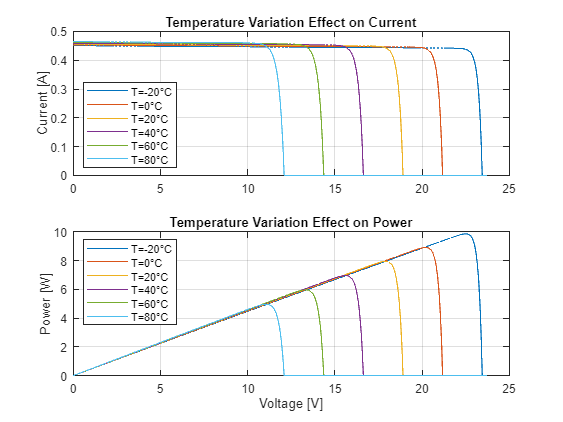

subplot(2,1,2)
    for T=-20:20:80
        I = pv_math_CTJ(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,m);
        plot(V,V.*I)
        hold on
        grid on
    end
    legend('T=-20°C','T=0°C','T=20°C','T=40°C','T=60°C','T=80°C')
    legend('Location','northwest')
    title('Temperature Variation Effect on Power')
    ylabel('Power [W]')
    xlabel('Voltage [V]')

### Variation with irradiance

I-V

close all
clear all
Ns=7;
Np=1;
%G=1367;
T=25;               %Ref. Temperature
Isc=0.457; %cell
Voc=Ns*2.62; %array
A=1.3;
Rs=1.3;
Rsh=362;
size=26.5;          % in cm^2
Ki=0.0114*size;    % in [mA / cm^2 / deg C]
Kv=-6.19;         % in [mV / deg C]  
i=0;
V=0:0.01:Voc+0.01;

figure(4)
set(gcf,'color','w');
subplot(2,1,1)
    for G=1367-1200:200:1367
        I = pv_math_CTJ(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
        plot(V,I)
        hold on
        grid on
    end
    legend('φ=167 W/m^2','φ=367 W/m^2','φ=567 W/m^2','φ=767 W/m^2','φ=967 W/m^2','φ=1167 W/m^2','φ=1367 W/m^2')
    legend('Location','southwest')
    title('Radiation flux Effect on Current')
    ylabel('Current [A]')
    %xlabel('Voltage [V]')

P-V

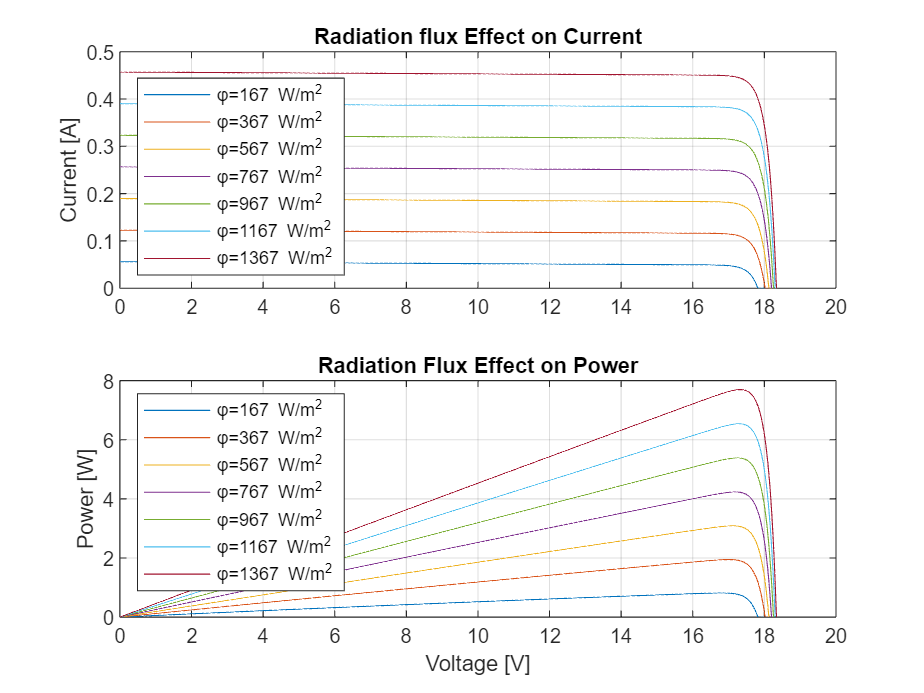

subplot(2,1,2)
    for G=1367-1200:200:1367
        I = pv_math_CTJ(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
        plot(V,I.*V)
        hold on
        grid on
    end
    legend('φ=167 W/m^2','φ=367 W/m^2','φ=567 W/m^2','φ=767 W/m^2','φ=967 W/m^2','φ=1167 W/m^2','φ=1367 W/m^2')
    legend('Location','northwest')
    title('Radiation Flux Effect on Power')
    ylabel('Power [W]')
    xlabel('Voltage [V]')

# Calculating intersection R vs IV curve

This part calculates the intersection of the PV curve with a value of resistance to check with the implementation. It uses a downloaded function called InterX

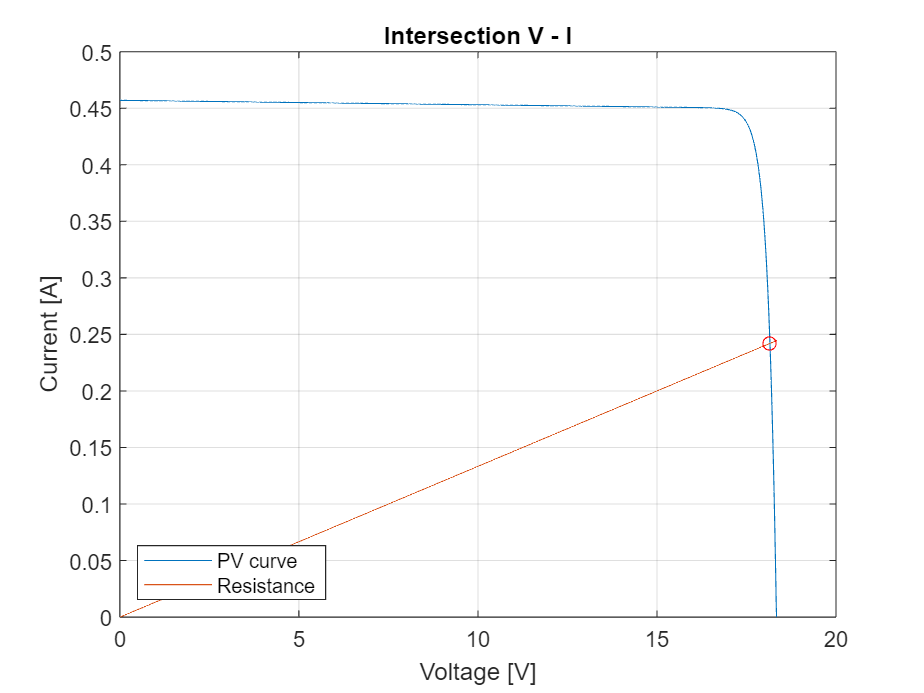

clear all
close all
%First get IV curve
Ns=7;
Np=1;
G=1367;
T=25;
Isc=0.457; %cell
Voc=Ns*2.62; %array
A=1.3;
Rs=1.3;
Rsh=362;
size=26.5;          % in cm^2
Ki=0.0114*size;    % in [mA / cm^2 / deg C]
Kv=-6.19;         % in [mV / deg C]  
i=0;
V = 0:0.01:Voc+0.01;
I = pv_math_CTJ(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);

% Now get R curve:
Rload = 75;
Ires = V / Rload;

%now calculate intersection points
Pint = InterX([V;I],[V;Ires]);

figure(5)
set(gcf,'color','w');
    plot(V,I)
    grid on
    hold on
    plot(V,Ires)
    plot(Pint(1,:),Pint(2,:),'ro')
    legend('PV curve', 'Resistance')
    legend('Location','southwest')
    title('Intersection V - I')
    ylabel('Current [A]')
    xlabel('Voltage [V]')

## Testing

clear all
close all
%First get IV curve
Ns=7;
Np=1;
G=1367;
T=25;
Isc=0.457; %cell
Voc=Ns*2.62; %array
A=1.3;
Rss=1.3;
Rsh=362;
size=26.5;          % in cm^2
Ki=0.0114*size;    % in [mA / cm^2 / deg C]
Kv=-6.19;         % in [mV / deg C]  
i=0;
 
V = 0:0.01:Voc+0.01;
Iref=zeros(1,length(V));
for m=1:length(V)
    q = 1.6e-19;                    %Electron charge
    k = 1.38e-23;                   %Boltzmann constant
    Tcell = 273 + T;                %Cell temperature in Kelvin
    vt = (A * k * Tcell * Ns) / q;  %Thermal voltage Equation(5)

    Isc_T = Isc + ((Isc * (Ki / 1000)) * (T - 25));  % Isc temperature coef Equation(6)
    Voc_T = Voc + ((Voc * (Kv / 1000)) * (T - 25));  % Voc temperature coef Equation(7)
    Is = Isc_T / (exp(Voc_T / vt) - 1);              % Reverse saturation current Equation(8)
    Iph = Isc_T * (G / 1367);                        % Photon current Equation(9)

    %Iref(m)= Np*Iph-Np*Is*(exp(q*(V(1,m)/Ns+i*Rss/Np)/(k*Tcell*A) ) -1) -(Np*V(1,m)/Ns+i*Rss)/Rsh ;
    %Iref(m) = Iph - (Is * (exp((V(m) + (i * Rss)) / vt) - 1)) - ((V(m) + (i * Rss)) / Rsh);
    Iref(m) = Iph - (Is * (exp((V(m) + (i * Rss)) / vt) - 1)) - ((V(m)/Ns + (i * Rss)) / Rsh);
    if Iref(m) < 0 
        Iref(m)= 0;
    end

end
I=Iref;

R = [15,28,40,65,100];
Ires1=V/R(1);
Ires2=V/R(2);
Ires3=V/R(3);
Ires4=V/R(4);
Ires5=V/R(5);

%now calculate intersection points
Pint1 = InterX([V;I],[V;Ires1])

Pint1 =     6.8147
    0.4543


Pint2 = InterX([V;I],[V;Ires2])

Pint2 =    12.6562
    0.4520


Pint3 = InterX([V;I],[V;Ires3])

Pint3 =    17.5000
    0.4375


Pint4 = InterX([V;I],[V;Ires4])

Pint4 =    18.1104
    0.2786


Pint5 = InterX([V;I],[V;Ires5])

Pint5 =    18.2148
    0.1821


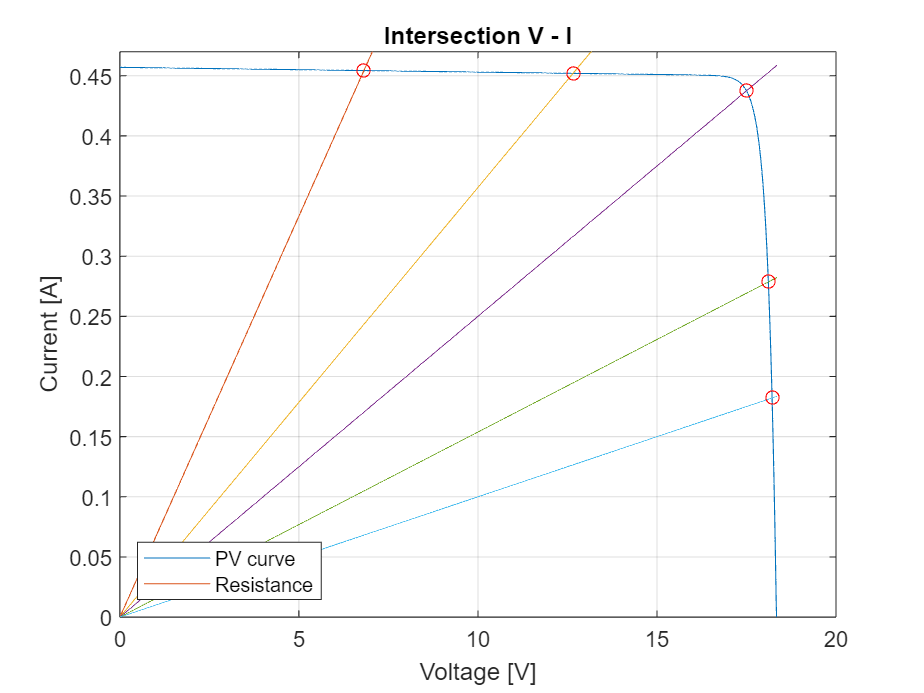


figure(6)
set(gcf,'color','w');
    plot(V,Iref)
    grid on
    hold on
    plot(V,Ires1,V,Ires2,V,Ires3,V,Ires4,V,Ires5)
    plot(Pint1(1,:),Pint1(2,:),'ro',Pint2(1,:),Pint2(2,:),'ro',Pint3(1,:),Pint3(2,:),'ro',Pint4(1,:),Pint4(2,:),'ro',Pint5(1,:),Pint5(2,:),'ro')
    legend('PV curve', 'Resistance')
    legend('Location','southwest')
    title('Intersection V - I')
    ylabel('Current [A]')
    xlabel('Voltage [V]')
    ylim([0.0 0.47])

## Calculating the value of Rload

We are testing what are the values of the load to check the different (I,V) points of the PV emulator.

To do so, first, we are going to use the I and V values of different points of the IV desired curve. We know this will intersect with the value of the Rload, so, a proposal could be to use to resistances in series, R1 & R2, with another one in parallel, R3, so, the total equivalent load would be: 

Rload = (R1+R2) || R3.

R1 is the variable resistance that we have, this variable resistance has a maximum dissipation power of 0.6W, so this is a first condition.

It is possible to fix R2 with other values (R2 will limit the current on R1, so it limits the dissipation power, it has to be close to R1) so R3 is defined with the previous constants. In the following calculation, two outputs are interesting: What is the value of R3? and what is the dissipation P1? 

close all
I=0.3;
V=9.9;
R1=10;
R2=30;
[RL,R3,I1,P1,P2,P3] = TESTR3(R1,R2, I, V)

RL = 33

R3 = 188.5714

I1 = 0.2475

P1 = 0.6126

P2 = 1.8377

P3 = 0.5197

Now that R3 is fixed, we can start make variations on R1, to see what is the range of Rload that can be produced.

First, it is necessary to check that the dissipation power on R1 does not exceed the 0.5W (0.1W of margin) of dissipation from R1. When the dissipation power P1 reaches 0.5, that would be the maximum that R1 can reach.

Then, the variation of R1 will also affect Rload, this will produce a range of values that can be used to get different values of V and I in the IV curve of the emulator.

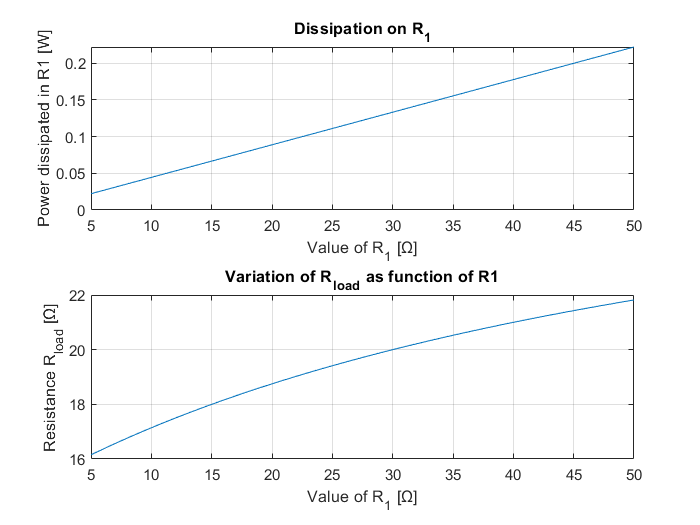

R3=27;
R1=5:1:50;
[RL,I1,P1,P2,P3] = testRL(R1,R2,R3,I,V);
figure(9)
subplot(2,1,1)
plot(R1,P1)
hold on
grid on
title('Dissipation on R_1')
xlabel('Value of R_1 [Ω]')
ylabel('Power dissipated in R1 [W]')
subplot(2,1,2)
R3=30;
RL=(R1+R2).*R3./(R1+R2+R3);
plot(R1,RL)
hold on
grid on
title('Variation of R_{load} as function of R1')
xlabel('Value of R_1 [Ω]')
ylabel('Resistance R_{load} [Ω]')

### Value of Rload for Peak Power

In the case of peak power:

I=0.483;
V=10.2;
P_peak=I*V

P_peak = 4.9266

R1=20;
R2=50;
[RL,R3,I1,P1,P2,P3] = TESTR3(R1,R2, I, V)

RL = 21.1180

R3 = 30.2414

I1 = 0.1457

P1 = 0.4247

P2 = 1.0616

P3 = 3.4403

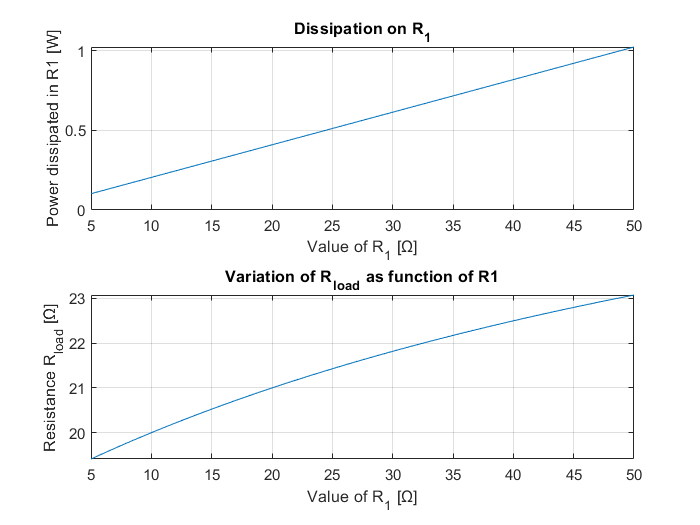

R3=30;
R1=5:1:50;
[RL,I1,P1,P2,P3] = testRL(R1,R2,R3,I,V);
figure(10)
subplot(2,1,1)
plot(R1,P1)
hold on
grid on
title('Dissipation on R_1')
xlabel('Value of R_1 [Ω]')
ylabel('Power dissipated in R1 [W]')
subplot(2,1,2)
R3=30;
RL=(R1+R2).*R3./(R1+R2+R3);
plot(R1,RL)
hold on
grid on
title('Variation of R_{load} as function of R1')
xlabel('Value of R_1 [Ω]')
ylabel('Resistance R_{load} [Ω]')

### Other values of Rload

In other cases:

I=0.49;
V=9.9;
P_peak=I*V

P_peak = 4.8510

R1=20;
R2=100;
[RL,R3,I1,P1,P2,P3] = TESTR3(R1,R2, I, V)

RL = 20.2041

R3 = 24.2945

I1 = 0.0825

P1 = 0.1361

P2 = 0.6806

P3 = 4.0343

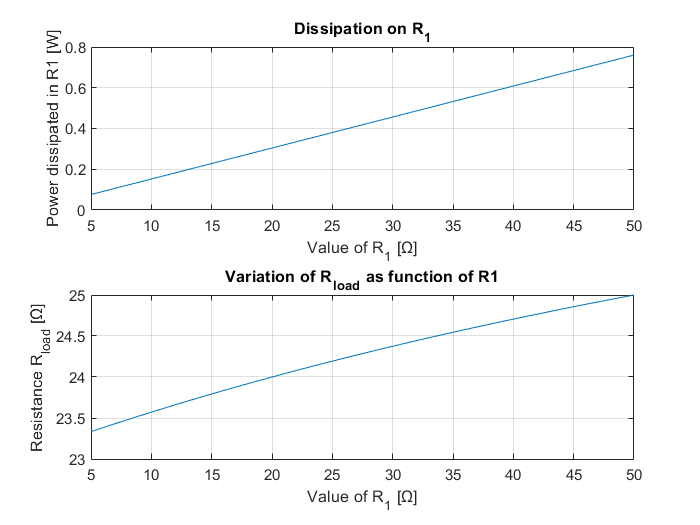

R3=27;
R1=5:1:50;
[RL,I1,P1,P2,P3] = testRL(R1,R2,R3,I,V);
close all
figure(11)
subplot(2,1,1)
plot(R1,P1)
hold on
grid on
title('Dissipation on R_1')
xlabel('Value of R_1 [Ω]')
ylabel('Power dissipated in R1 [W]')
subplot(2,1,2)
R3=30;
RL=(R1+R2).*R3./(R1+R2+R3);
plot(R1,RL)
hold on
grid on
title('Variation of R_{load} as function of R1')
xlabel('Value of R_1 [Ω]')
ylabel('Resistance R_{load} [Ω]')

## Resistance vs curve

Using the values of the MSP IonSat Solar panel, which has 4 blocks of 4S1P in parallel, which give in total 4S4P , The value of A is found from this article Tsai, H. L., Tu, C. S., & Su, Y. J. (2008, October). Development of generalized photovoltaic model using MATLAB/SIMULINK. In *Proceedings of the world congress on Engineering and computer science* (Vol. 2008, pp. 1-6).

clear all

Ns=4;
Np=1;
G=1000;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
m=0;
V=0:0.01:Voc+0.2;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,m);
R10=10;
R15=15;
R22=22;
R35=35;

figure(12)
plot(V,I)
hold on
plot(V,V/R10)
plot(V,V/R15)
plot(V,V/R22)
plot(V,V/R35)
grid on
xlim([0 11])
ylim([0 0.6])
legend('IV curve','R=10','R=15','R=22','R=35','Location',"best")
figure(13)
plot(V,I.*V)
hold on
plot(V,V.^2/R10)
plot(V,V.^2/R15)
plot(V,V.^2/R22)
plot(V,V.^2/R35)
grid on
xlim([0 11])
ylim([0 6])
legend('PV curve','R=10','R=15','R=22','R=35','Location',"best")

# PV emulator based on diodes

Three parameters have to be estimated

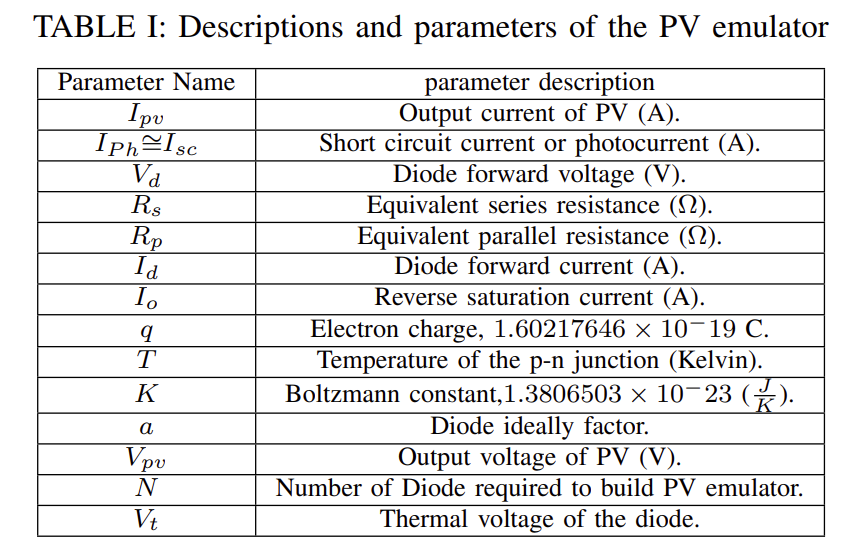

clear all
close all
%First get IV curve
Ns=7;
Np=1;
%G=1367;
Isc=0.457; %cell
Voc=Ns*2.62; %array
Acell=1.85;
%Rs=1.3;
%Rsh=362;
Vmp = 17.33;
Imp = 0.4443;

q = 1.60217646e-19;                           % Electron charge
K = 1.3806503e-23;                          % Boltzmann constant
T = 150;
Tcell = 273+T;                         % Cell temperature in Kelvin

Io = 10e-6;
a = 1.85;
Vt=(a*K*Tcell*Ns)/q; 

N = (q*Voc) / (a*K*Tcell * log( Isc/Io +1));
A = a*Vt/Imp;